N25 = 4.7224e+21

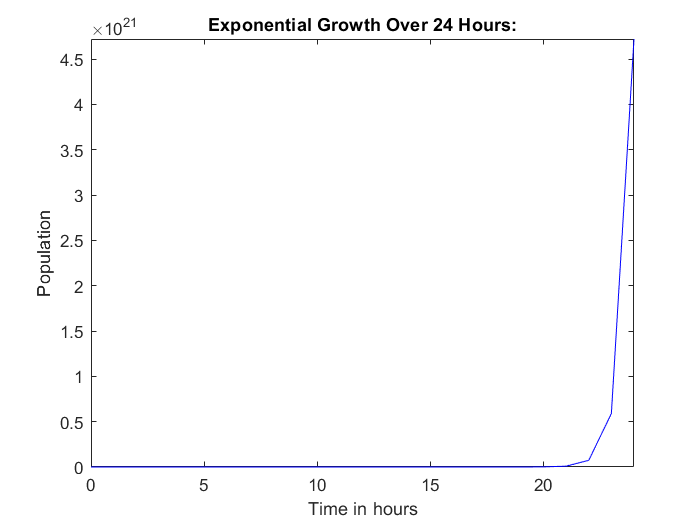

volume_cubic_meter = 9.4447e+03

volume_liter = 9.4447e+06

N_L = 5.0000e+14

time_in_hours = 14.0617

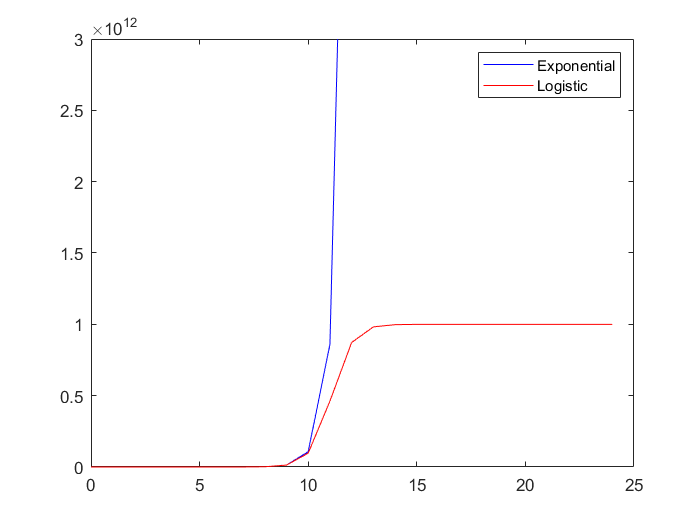

   1.0e+11 *

  Columns 1 through 10

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0021    0.0167    0.1324

  Columns 11 through 20

    0.9696    4.6207    8.7297    9.8214    9.9773    9.9972    9.9996   10.0000   10.0000   10.0000

  Columns 21 through 25

   10.0000   10.0000   10.0000   10.0000   10.0000



plot(Nprey,Npred);
xlabel('Number of prey');
ylabel('Number of predator');
hold on;
max_U = max(Nprey);
max_V = max(Npred);
N = 20;
range_U = 0:(max_U/N):max_U;
range_V = linspace(0,max_V,N+1);
[UU,VV] = meshgrid(range_U, range_V);
vel_U = alpha*UU - gamma*UU.*VV;
vel_V = epsilon*gamma*UU.*VV - beta*VV;
h = quiver(range_U,range_V,vel_U,vel_V,0.5);
set (h, "maxheadsize", 0.005);
axis([0 Inf 0 Inf]);
hold off;